# Design and Comparison of FIR and IIR Filters (200 Points)

Welcome to Lab 3!

In this lab, you will design and compare FIR and IIR filters. Refer to the below diagram for the lab.  

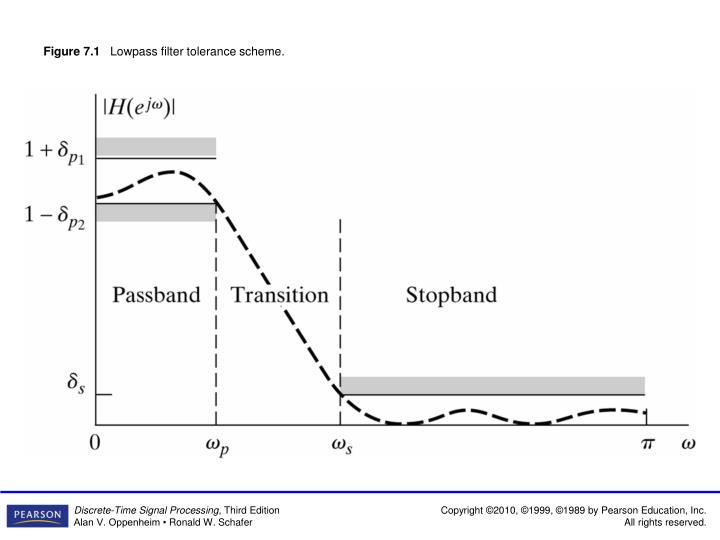

## FIR Filter Design (40 Points)

Now, we will design FIR filters satisfying the following specifications: 

- 
$$\omega_p =0.4\pi
$$


- 
$$\omega_s = 0.6\pi
$$
 

- 
$$\delta_{p_1}=\delta_{p_2}=0.01, \;\;\delta_s=0.01$$


### Windowing Method (20 Points)

Now, using the Kaiser window, come up with a window-based FIR filter with the above specifications (presented just after the first image of the notebook)

For theoretical understanding, see (i) page 499, Example 7.8 of the Second Edition of the textbook, or (ii) page 569, Section 6.1 of Third Edition of your textbook.  

- From your theoretical understanding, what is the filter order (approx)?  23 (order as A=40, $\Delta \omega =0\ldotp 2\pi ,\textrm{we}\;\textrm{take}\;\textrm{the}\;\textrm{lerger}\;\textrm{integer}\ldotp$) 

- Open "filterDesigner" tool (you can open it by typing *filterDesigner* in the Matlab command window as shown below.)

                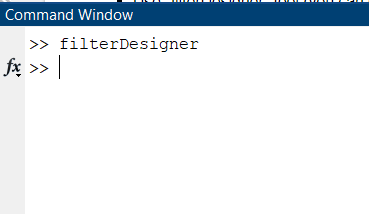

       Open the below view. Here you can specify frequency and magnitude specifications. 

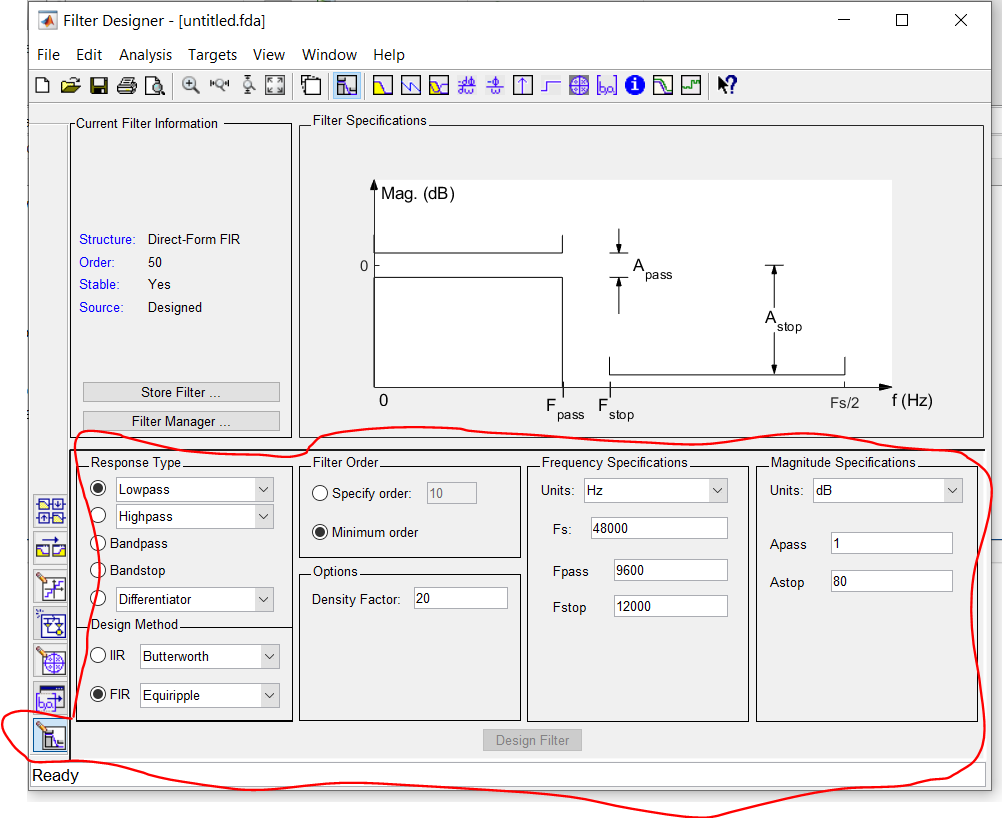

-   Obtain the coefficients of the filter. Write down the coefficients below. 

%close all;  %closes all other workable windows
clear all;  %clear our workspace
%clear;
% ASSIGN THE FILTER COEFFICIENTS TO "b". 
b = [-0.002907211955384275854641362712982299854,
    -0.004903665350658096937219720956591118011,
    0.007556835867128868303166377984325663419,
     0.011022695479796449855025564090738043888, 
     -0.015522540177083104726007967144596477738,
     -0.021399197607360729428416235009535739664,
      0.029235890996987257128836290576145984232,
       0.040134591714861472810937925714824814349,
       -0.056471920114176024640961770728608826175,
       -0.084468388232154023587128222061437554657,
        0.147031071648377920091377291100798174739,
         0.450691837729664368517035200056852772832,
          0.450691837729664368517035200056852772832,
           0.147031071648377920091377291100798174739,
           -0.084468388232154023587128222061437554657,
           -0.056471920114176024640961770728608826175,
            0.040134591714861472810937925714824814349,
             0.029235890996987257128836290576145984232,
             -0.021399197607360729428416235009535739664,
             -0.015522540177083104726007967144596477738,
              0.011022695479796449855025564090738043888,
               0.007556835867128868303166377984325663419,
               -0.004903665350658096937219720956591118011,
               -0.002907211955384275854641362712982299854];

- Does the number of entries in $b$ correspond to the above theoretically obtained filter order?

           * ANSWER Yes the length of filter is 24 so order is 24-1=23.*

- Observe the pole-zero plot, magnitude and phase response, group delay plot and make your comments.  

           * ANSWER  in Pole zero plot we got 23 poles at (0,jexp(-50)) ~ origin and 23 zeros in which few are on Left side and  lesser on right side so it's *

*                                stable.*

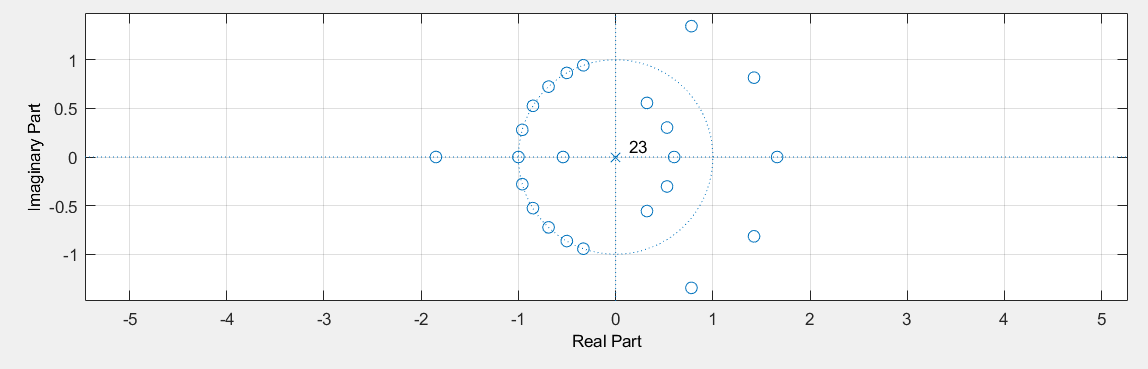

*                              The Magnitude plot matches specifications*. 

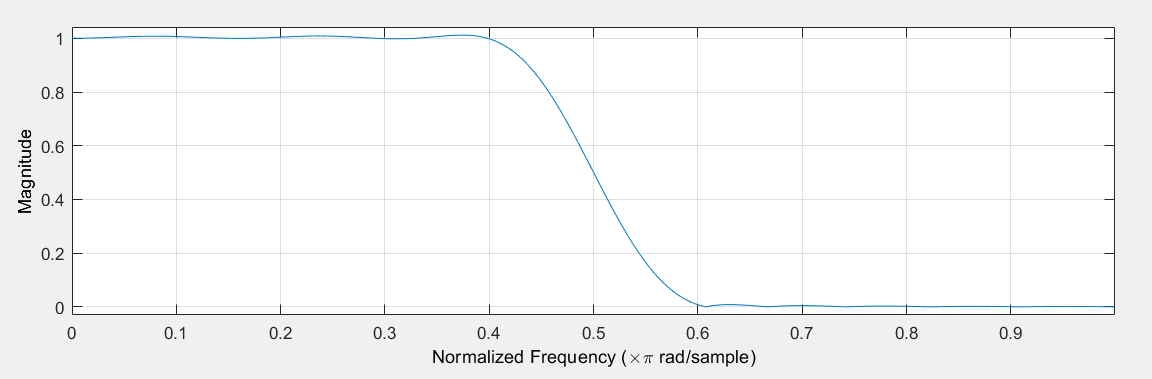

                                The phase plot  has constant gradient till *0.6*$\pi$ after which it goes on varying .

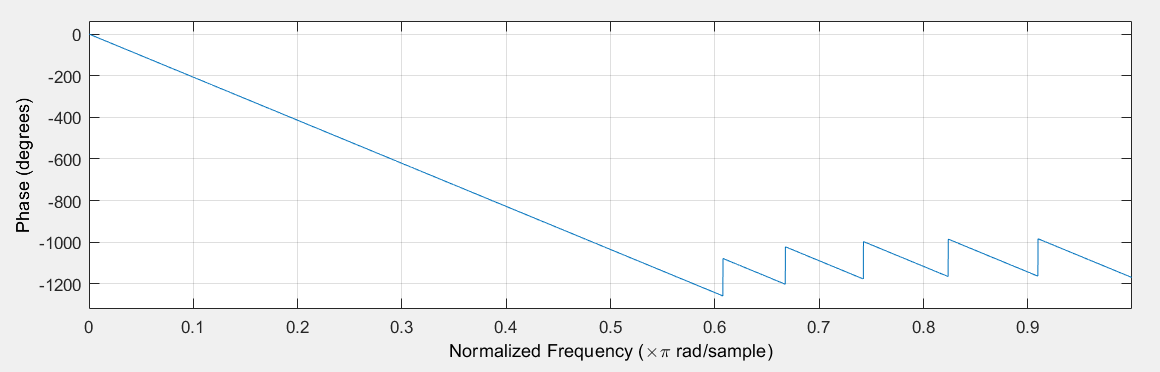

                                The group delay plot is constant at 11.5 which is correct as order is 23 ie.11.5*2.

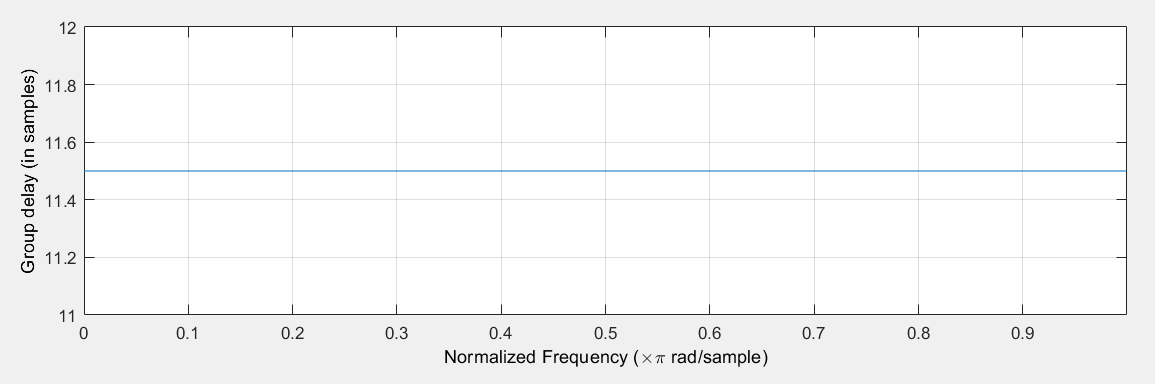

### Min-Max Method (20 Points): 

You already know that the the FIR filter designed using the windowing method has minimimum mean squared error with respect to the ideal filter response. Now, we will design a filter which minimizes the maximum error with respect to the ideal filter. Now watch "Week-6 Video-3.mp4" to understand the theory behind the optimal min-max FIR filter design method. Design an FIR filter satisfying the  specifications presented just after the first image of the notebook using  [firpm](https://in.mathworks.com/help/signal/ref/firpm.html).

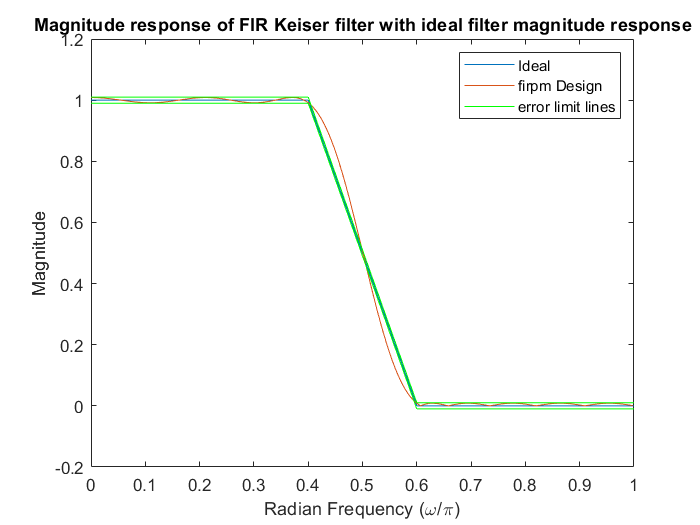

M=19+2;%By substuting all values in the Keiser approximation we get M as 19.
% %we increased it as we were getting error > EMax on looking at the graph..
N=10; %As thats the integer greater equal M/2

f = [0 0.4 0.6 1];
a = [1 1 0 0];
a1= a+0.01;
a2= a-0.01;
b = firpm(M,f,a);

[h,w] = freqz(b);
plot(f,a,w/pi,abs(h))
hold on
plot(f,a1,'-g');
plot(f,a2,"-g");
hold off
legend('Ideal','firpm Design',"error limit lines");
xlabel('Radian Frequency (\omega/\pi)');
ylabel ('Magnitude');
title("Magnitude response of FIR Keiser filter with ideal filter magnitude response");

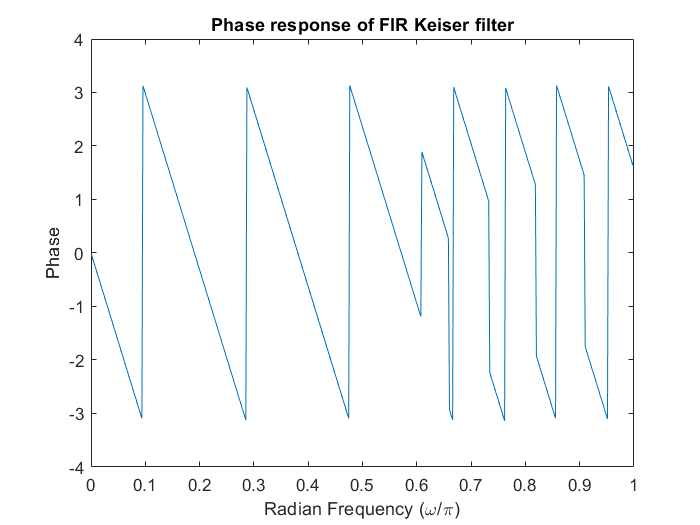

plot(w/pi,angle(h))
xlabel('Radian Frequency (\omega/\pi)');
ylabel ('Phase');
title("Phase response of FIR Keiser filter");

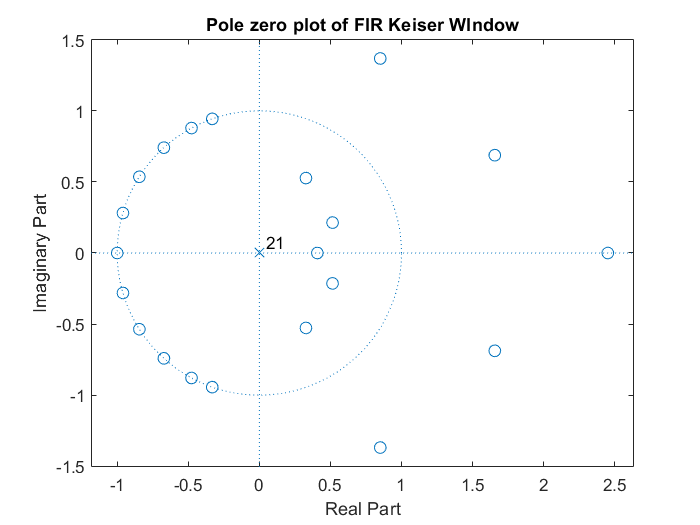

zplane(b,1);
title("Pole zero plot of FIR Keiser WIndow");

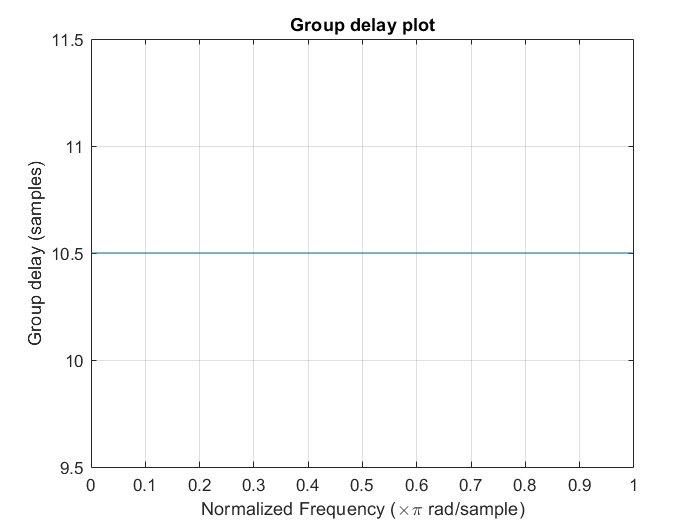

grpdelay(b,1)
title("Group delay plot")

           % WRITE YOUR CODE HERE





- Observe the pole-zero plot, magnitude and phase response, group delay plot and make your comments.      

           * ANSWER Looking at magnitude plot and comparing it with given specifications I was able to get with order greater equal 21.*

*                            In that case we see the design hold all conditions and group delap plot shows constant delay of 10.5 which is 21/2.*

*                            pole zero plot gives 21 poles a origin and more zeros on left plane than right so our filter is stable.*

*                            The phase plot keeps on oscillating .*

- Give a comparison with the filter obtained using the windowing method above.  

           * ANSWER In windowing methord the phase was constant earlier and later varied but here the phase is varying continously.*

*                        While both do the job but designing with windowing is simpler while we can fine tune our design for higher efficiency         *

*                        and less computations in case of ***Parks-McClellan  Filter design algorithm.**

## IIR Filter Design (100 Points)

In this part, we will solve Example 5 of Chapter 7 of Oppenheim and Schafer textbook using the *filterDesigner* tool. Although you need to know how impulse invariance and bilinear transform methods work, you almost never design discrete-time filters manually. Almost always, you will use some tools, such as *filterDesigner* MATLAB. 

**Note:**  From this course point of view, you should know how to manually design filters using impulse invariance and bilinear transform for IIR filters, and window and equiripple (also called as minimax or Parks-McClellan methods) for FIR filters. 

**References:** 

- Example 5 of Chapter 7 of Oppenheim and Shafer textbook, 3rd Edition (If you have the 2nd Edition, see Example 7.4, 7.5 and 7.6 for the IIR part starting from Page 458, and Section 7.5.1 on Page 503 for FIR part )

- [https://spinlab.wpi.edu/courses/ece503_2014/10-1intro_to_filter_design.pdf](https://spinlab.wpi.edu/courses/ece503_2014/10-1intro_to_filter_design.pdf)

- Relevant Week7 videos from EE321 Course. Watch "Week-7 Video-2.mp4" for the Bilinear Transform method for IIR Filter design method (note that we had skipped this in the theory part of the course)

Design the following filter: $\delta_{p_1} = \delta_{p_2} = 0.01, \;\;
\delta_s = 0.001, \;\; \omega_p = 0.4\pi, \;\; \omega_s = 0.6\pi
$using

- IIR Butterworth

- IIR Chebyshev Type 1

- IIR Chebyshev Type 2

- IIR Elliptic

- FIR Window - Kaiser

- FIR Equiripple 

and answer the following for each of the above methods: 

- Order of the filter

- A sentence on passband and stopband behaviour (in terms of monotonic and equiripple behaviour) 

- Copy and paste magnitude response, group delay and pole-zero plots and write your comments. 

An example is shown below for IIR Butterworth filter: 

### IIR Butterworth filter

Open the Filter Designer tool, by typing *filterDesigner *in the command window as shown below. 

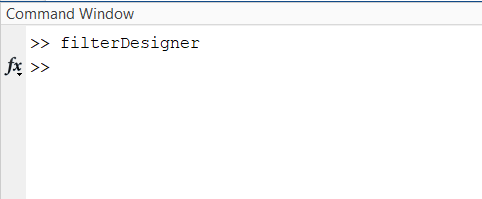

We first note that in the Filter Designer tool, for designing IIR filter,  it is assumed that $\delta_{p_1}=0
$ (red annotations in Fig. 1). Hence, in order to design the filter using this tool,  we first scale all the tolerance parameters, design the filter using the toolbox and then rescale them back.

- **Scaling the parameters:** Let $\delta_{p_1}',\; \delta_{p_2}'$and $\delta_s'$ be the new parameters.  We want to scale all the parameters according to the requirement that $\delta_{p_1}'=0$.  This implies, $1-\delta_{p_2}' = (1-\delta_{p_2})/(1+\delta_{p_1}) = (1-0.01)/1.01=  0.9802$. Hence, $\delta_{p_2}' = 1-0.9802=0.0198$. Similarly, $\delta_s' = \delta_s/(1+\delta_{p_1}) = 0.001/1.01 = 0.00099$. 

- **Filter Design:** Now, we feed these values in the Filter Designer tool  and design the filter (blue annotations in Fig. 1)

. 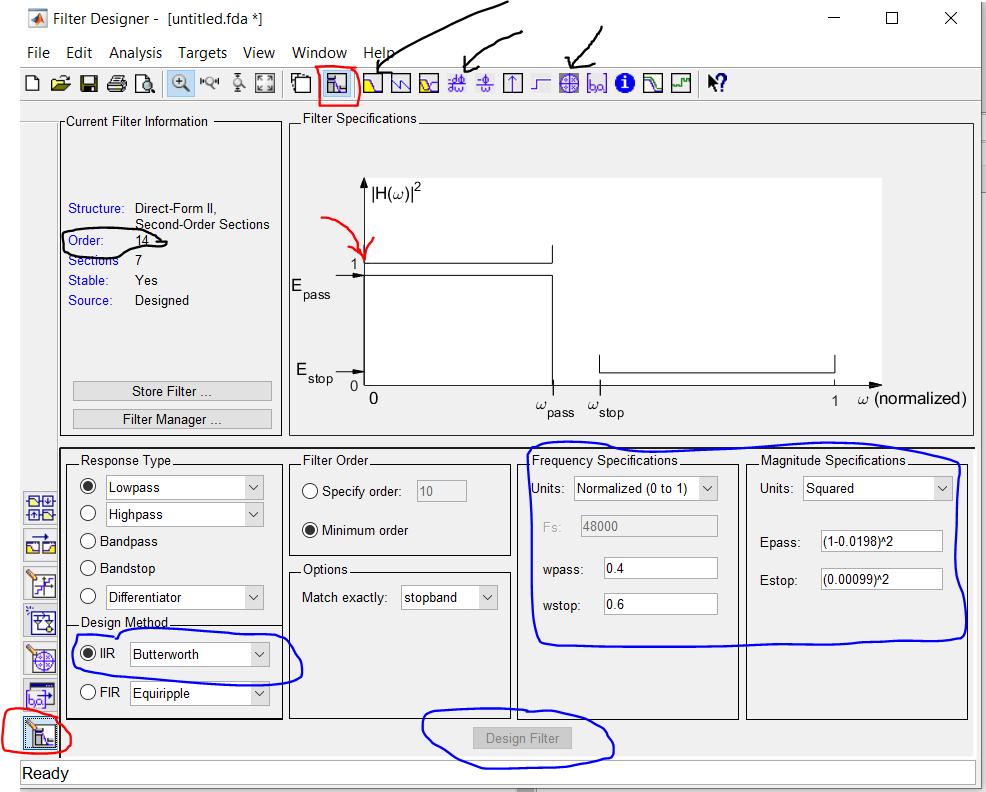

                                                      Fig 1: IIR Butterworth Filter Design

- **Rescaling parameters:**  Now, if you look at the magnitude response (by clicking on the tab besides the red annotated box), you can see that the above filter has gain of $0.9914$at $0.4\pi
$and $0.00099$at $0.6\pi$. Note that the design already satisfies the required specification. However, in some cases, if the required specification is not met, you need to rescale back the impulse response or numerator coefficients by $1+{\delta_{p_1}}$ to match the desired response. 

- **Filter Analysis: **Now, we will look at magnitude response, group delay and pole-zero plots and order of the filter (black annotations in Fig. 1). 

              - Filter order is 14. 

              - Both passband and stopbands have monotonic behaviour. 

              - There are 14 zeros at $-1$. Since all the poles are  inside the unit circle, the filter is stable. 

              - The group delay is highest in the transition band and below 15 in the passband. 

          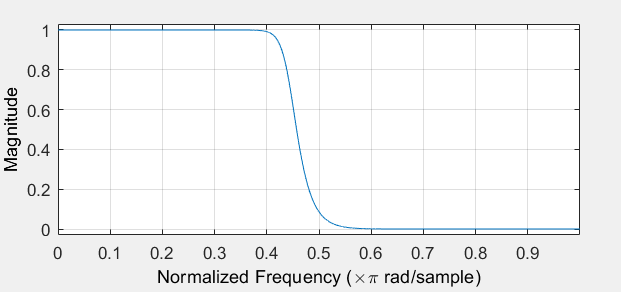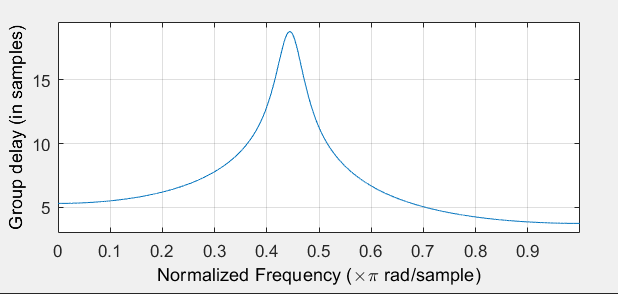

                               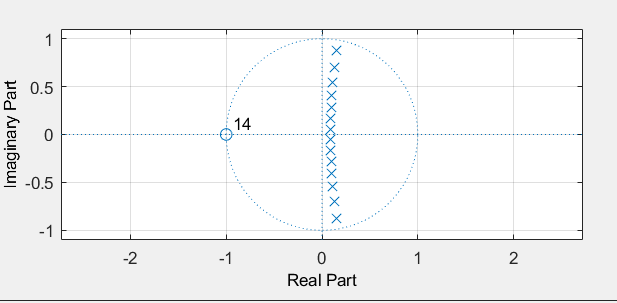

### IIR Chebyshev Type 1 (10 Points)

% Enter the filter coefficients
%Filter coefficients
C1num1=[1 2 1;
     1 2 1;
     1 2 1;
     1 2 1];
C1den1=[1	-0.546973251226029 0.898834056379833;
     1	-0.717257651116436 0.713657895463924;
     1	-1.01523783975706 0.548112152489310;
     1	-1.26265789161358 0.438338863184365];
C1Gain1=[0.337965201288451;
     0.249100061086872;
    0.133218578183062;
    0.0439202428926966];
C1net_gain= 0.980200000000000;


Answer the following:

- Order of the filter

*            ANSWER 8*

- A sentence on passband and stopband behaviour (in terms of monotonic and equiripple behaviour) 

*            ANSWER  Its passband has ripples but its stopband is monotonic . So its not equiripple.*

- Copy and paste magnitude response, group delay and pole-zero plots and write your comments. 

*            ANSWER*

*Magnitude response: It has ripples in passband while the stopband is monotonic. The ripples are strictly meeting requirements max error <0.1.*

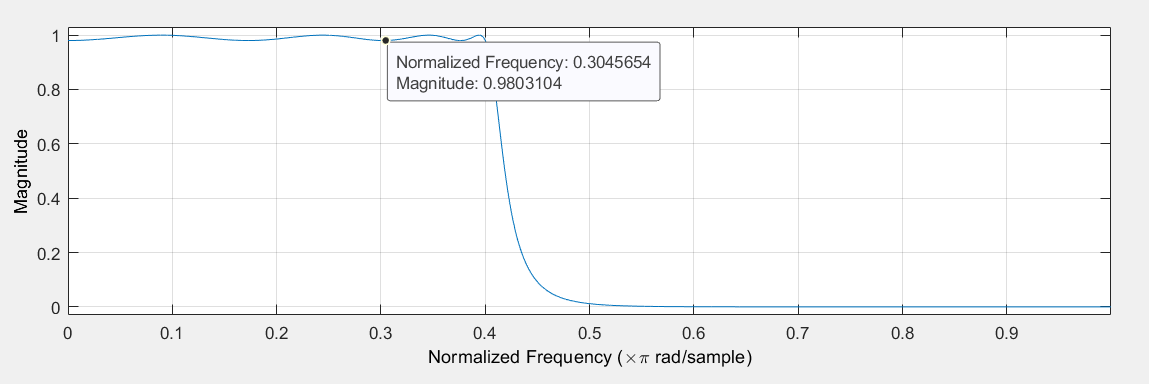

Group delay:  It goes to peak at frequency around 0.41$\pi \;\textrm{and}\;\textrm{then}\;\textrm{decreases}\;\ldotp$

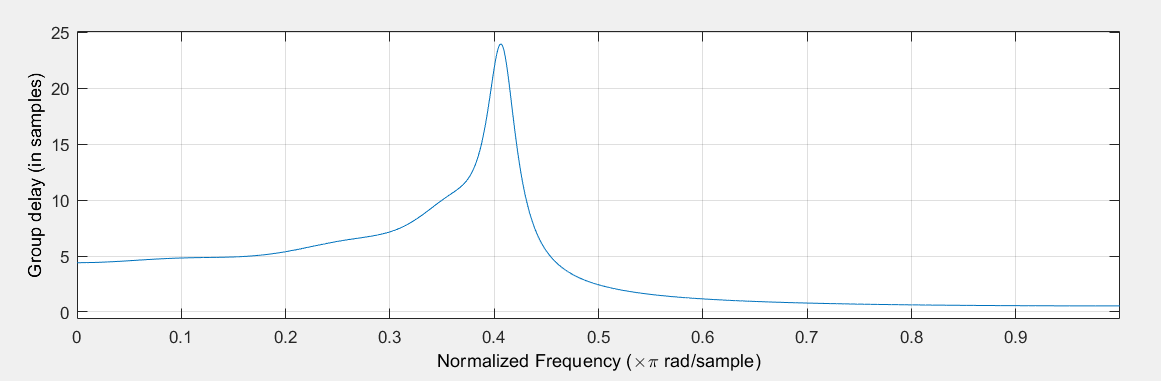

pole zero: We see all 8 poles are in RHP while all 8 zeros are at origin. The plot came as stable 

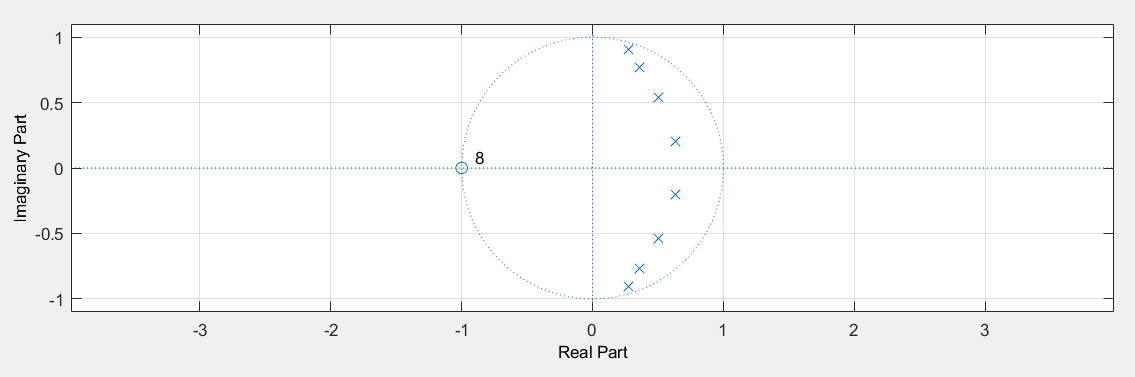

### IIR Chebyshev Type 2 (10 Points)

% Enter the filter coefficients
C2num=[1 0.652918507109619 1;
    1 0.930543693580330	1;
    1 1.43958909021804 1;
    1 1.92122021958431 1];
C2den= [1	-0.120507510600431	0.746181816416871;
    1	-0.00374235913859665	0.385595563398861;
    1	0.125444696672893	0.150772042799095;
    1	0.210144428408631	0.0280846983904862];
C2Gain= [0.612787125371457;
    0.471534755577049;
    0.371037558847207;
    0.315776482181452];
C2net_gain=1;

Answer the following:

- Order of the filter

*            ANSWER  8*

- A sentence on passband and stopband behaviour (in terms of monotonic and equiripple behaviour) 

*            ANSWER  Neither Passband or Stopband have visible ripples so in a sense it's equiripple with 0 ripples*

- Copy and paste magnitude response, group delay and pole-zero plots and write your comments. 

*            ANSWER*

*Magnitude response : Since there are no visible ripples it definitely meets the requirements .*

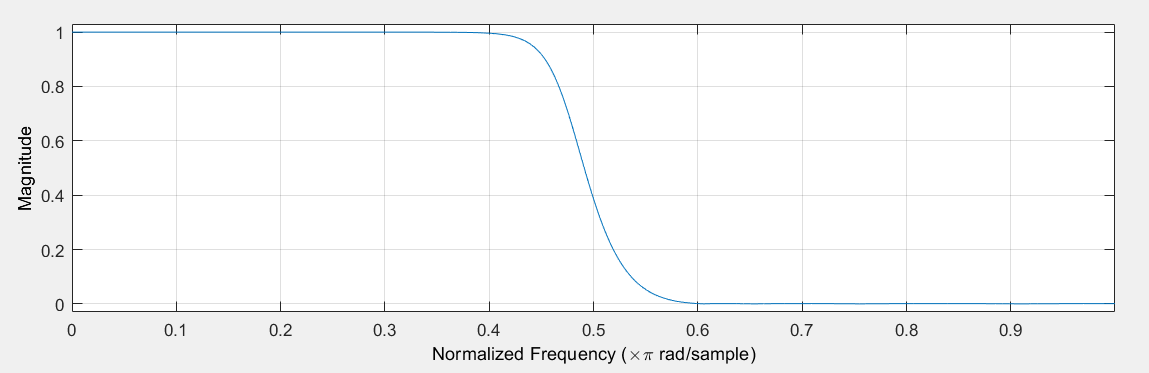

Group Delay:  It increases reaching a peak at 0.48$\pi$ after which it decreases motonically.

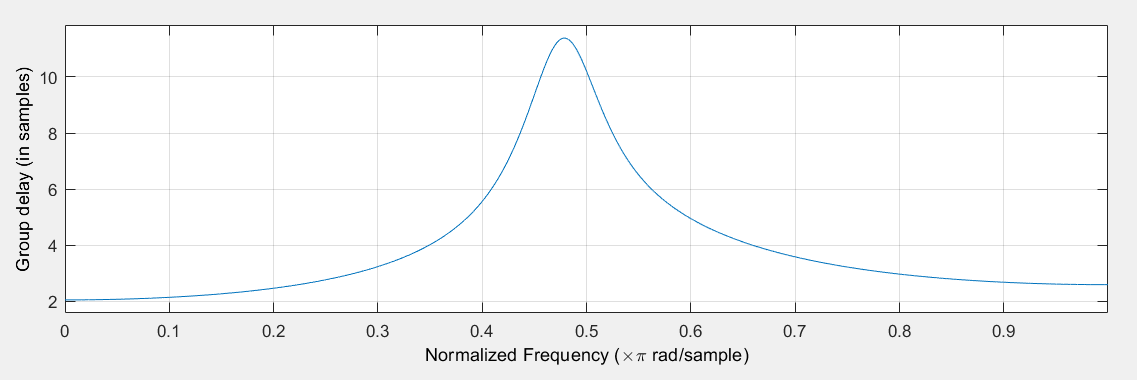

Pole zero plot : It has all 8 zeros in LHP and lesser number of poles on RHP. It's stable .

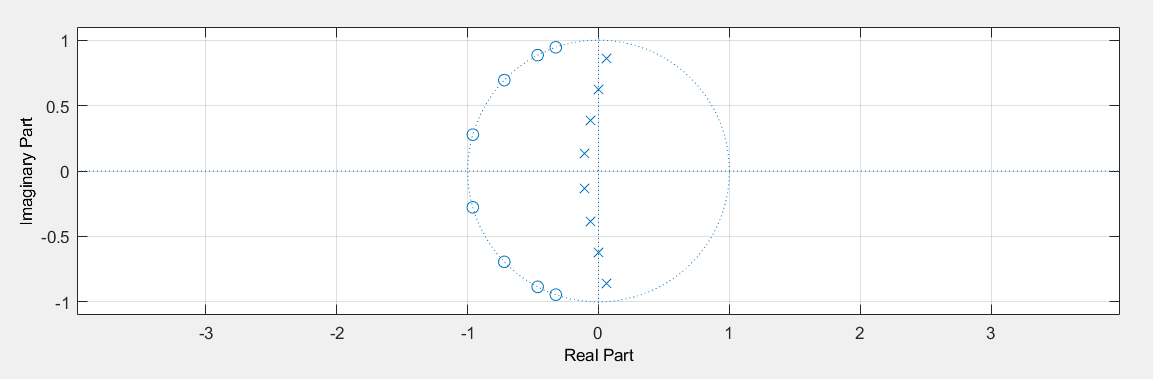

### IIR Elliptic (10 Points)

% Enter the filter coefficients
Ellnum=[1	0.694834977219487	1;
    1	1.72549033422845	1;
    1	0.219329979159607	1];
Ellden=[1	-0.689759787076362	0.589278853747360;
    1	-0.942628228849249	0.297853307679337;
    1	-0.522872296977416	0.873850552922561];
Ellgain=[0.774092875298320;
    1.56018344006996;
    0.0157242818381364];
Ellnet_gain=1;

Answer the following:

- Order of the filter

*            ANSWER 6*

- A sentence on passband and stopband behaviour (in terms of monotonic and equiripple behaviour) 

*            ANSWER  There are ripples in passband while stopband is monotonic.*

- Copy and paste magnitude response, group delay and pole-zero plots and write your comments. 

*            ANSWER*

*Magnitude Reaponse :  The passband has ripples with net error 0.02<0.1 so it meets requirements.*

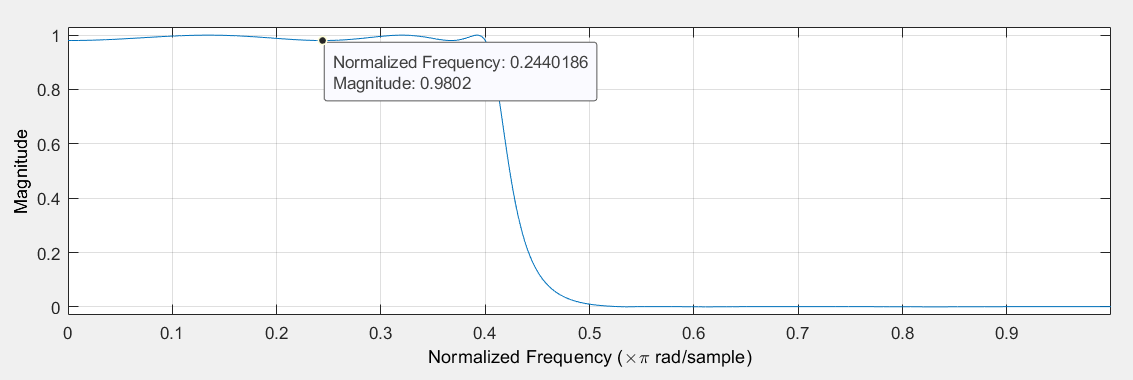

Group delay : The maximum group delay occurs at frequency 18.44$\pi$ which decreases after that.

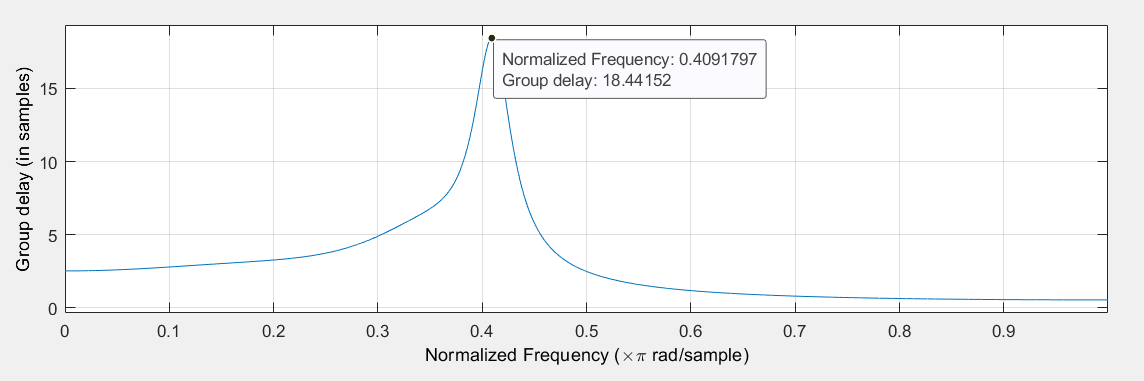

Pole zero plot: It has all 6 zeros on unit circle in LHP and all 6 poles in RHP. The filter is stable.

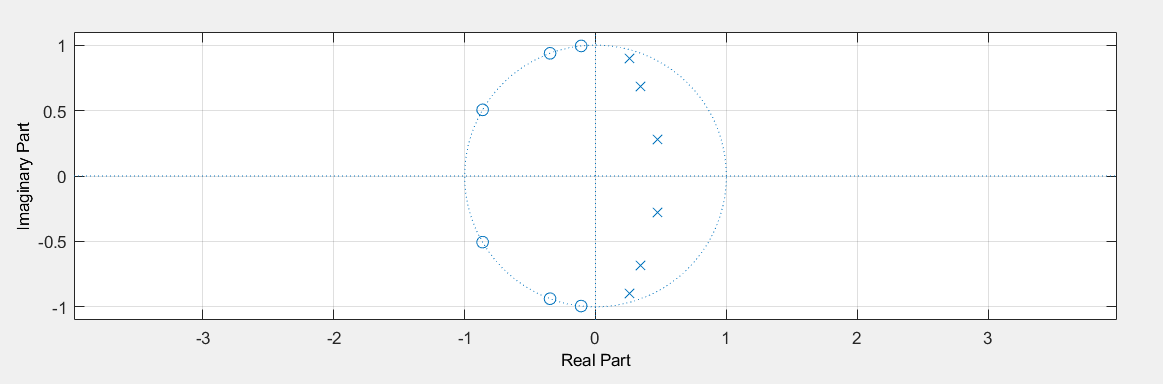

### FIR Window - Kaiser (10 Points)

% Enter the filter coefficients
Kaiser_num=[-0.000248008102503338	0.000533374457591009	0.000955506925690995	-0.00154968707202433	-0.00235608304490556	0.00342065549295198	0.00479681083291731	-0.00654832668496626	-0.00875444824748636	0.0115187774745581	0.0149850623958054	-0.0193662614808247	-0.0250010530838665	0.0324725189942208	0.0428854227839861	-0.0586188547145853	-0.0858846674984382	0.147517760688666	0.449241499883213	0.449241499883213	0.147517760688666	-0.0858846674984382	-0.0586188547145853	0.0428854227839861	0.0324725189942208	-0.0250010530838665	-0.0193662614808247	0.0149850623958054	0.0115187774745581	-0.00875444824748636	-0.00654832668496626	0.00479681083291731	0.00342065549295198	-0.00235608304490556	-0.00154968707202433	0.000955506925690995	0.000533374457591009	-0.000248008102503338];

Answer the following:

- Order of the filter

*            ANSWER  37*

- A sentence on passband and stopband behaviour (in terms of monotonic and equiripple behaviour) 

*            ANSWER Both are monotonic without ripples.*

- Copy and paste magnitude response, group delay and pole-zero plots and write your comments. 

*            ANSWER*

*Magnitude response: There are no ripples and it strictly meets the filter specifications.*

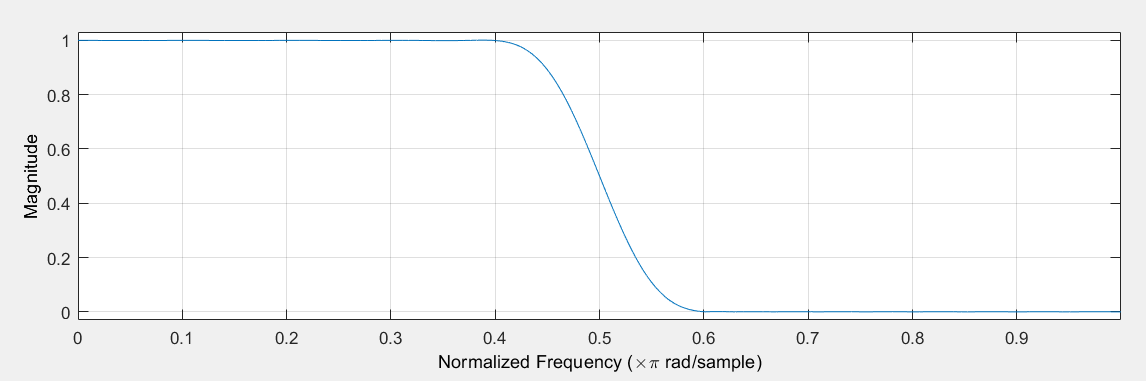

Group delay : Group delay is constant at 18.5 which is 37/2.

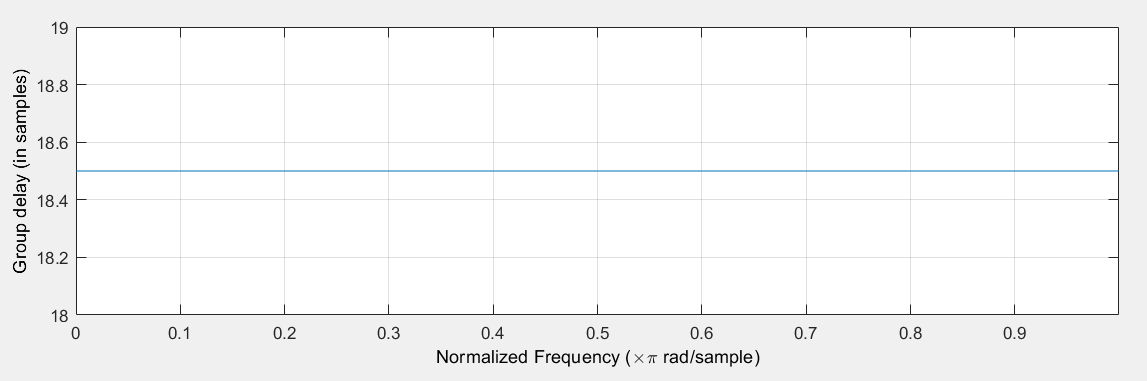

Pole zero plot : The plot has all poles at origin and some zeros in LHP while other in RHP.

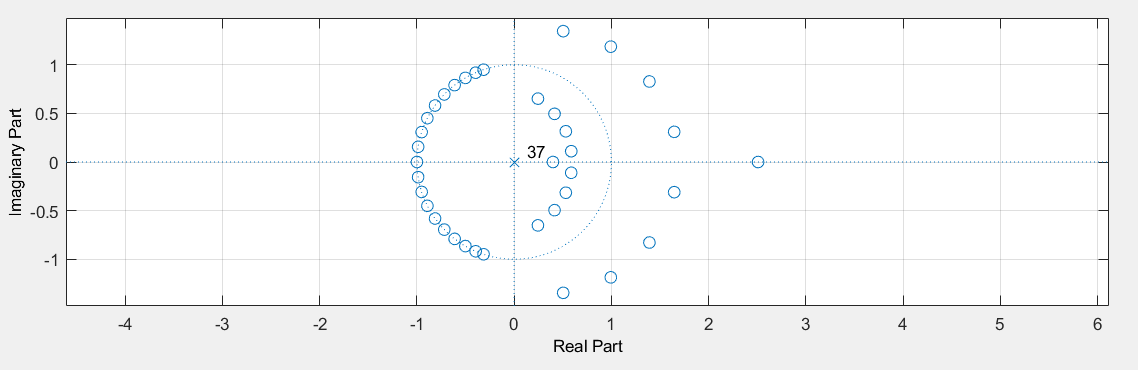

### FIR Equiripple (10 Points)

% Enter the filter coefficients
Equirnum=[-0.00255694603471546	-0.00759816315585803	-0.00150378550190926	0.0124251522917326	0.00549642501078310	-0.0221141921061701	-0.0138621891883555	0.0374390749425829	0.0308872916943620	-0.0659425442054115	-0.0738966529198243	0.157009809159164	0.438201641289614	0.438201641289614	0.157009809159164	-0.0738966529198243	-0.0659425442054115	0.0308872916943620	0.0374390749425829	-0.0138621891883555	-0.0221141921061701	0.00549642501078310	0.0124251522917326	-0.00150378550190926	-0.00759816315585803	-0.00255694603471546];

Answer the following:

- Order of the filter

*            ANSWER 25*

- A sentence on passband and stopband behaviour (in terms of monotonic and equiripple behaviour) 

*            ANSWER  Passband has ripples while stopband is monotonic. So its not equiripple.*

- Copy and paste magnitude response, group delay and pole-zero plots and write your comments. 

*            ANSWER*

*Magnitude response: It follows the specificatons as max error is 0.012 <0.1.*

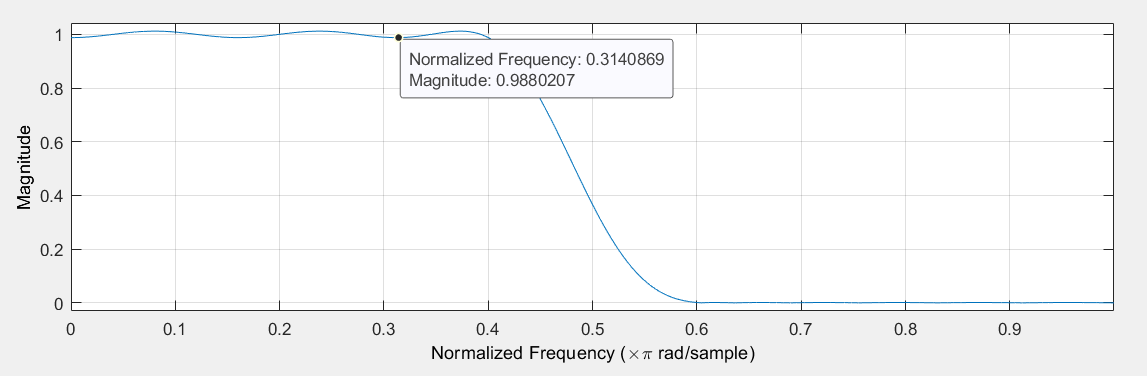

Group delay: Its constant at 12.5 which is 25/2

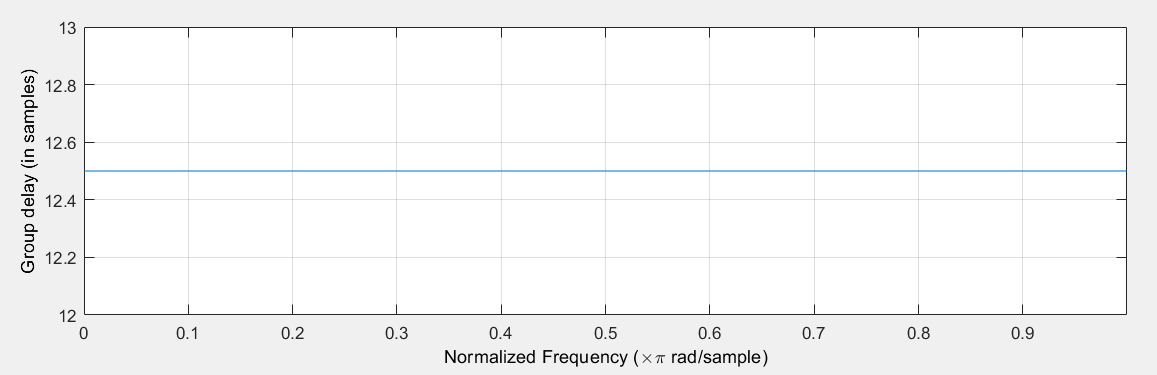

Pole zero plot: We got all 25 poles at origin with some zeros in LHP and others in RHP. The system is stable.

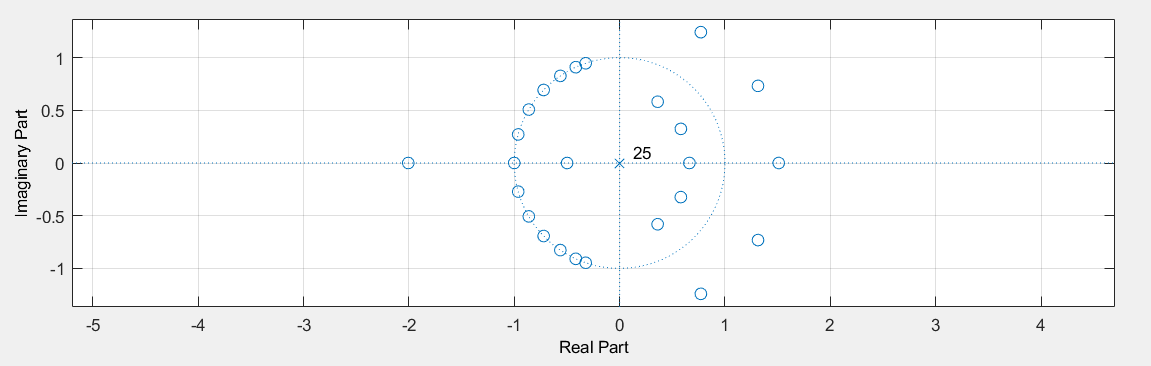

### Common Questions (50 Points):

After all the filter designs are completed, answer the below questions. 

- Among IIR filters, which filter gives the lowest order? What is the practical use of having a lowest order filter (think in terms of number of multiplications in the implementation)? 

            *ANSWER IIR Elliptic filter had the lowest order of 6 . Lower order will require less coefficients to be computed which will save computation power.*

- Among the FIR filters, which method gives the lowest order? Compare this with orders of IIR filters. 

            *ANSWER FIR Equiripple gave the lowest order of 25 but its much higher than IIR filters. So practically IIR filters work much better than FIR.*

- For a given filter specification, if you want the filter order to be as small as possible, which implemetation would you choose, FIR or IIR? Which one among them? 

            *ANSWER I would choose IIR Elliptic type of filter as that gives required filter specifications with minumum order ( or coefficients). I just need to be extra careful to ensure the filter is stable .*

- FIR filters are always stable, but IIR filters may or may not be stable (True or False)? 

            *ANSWER True , IIR filters may be unstable  sometimes.*

- Comment on the group delays of FIR and IIR filters. Which design would you prefer (FIR or IIR) if the filter order is not important but a constant group delay is required? 

            *ANSWER FIR filter  (mainly Equiripple) as they give constant group delay so using them needs less additional setup.*

## Minimum-Phase Filters (60 Points)

Consider the following scenario, where a message sequence $x[n]$is sent over a wireless channel and you receive, $y[n]$, via a multi-path channel (modeled as an LTI system, represented within the red box) with system function: 

$H(z) = \frac{z^{-1}-1/3}{1-0.9z^{-1}}$. 

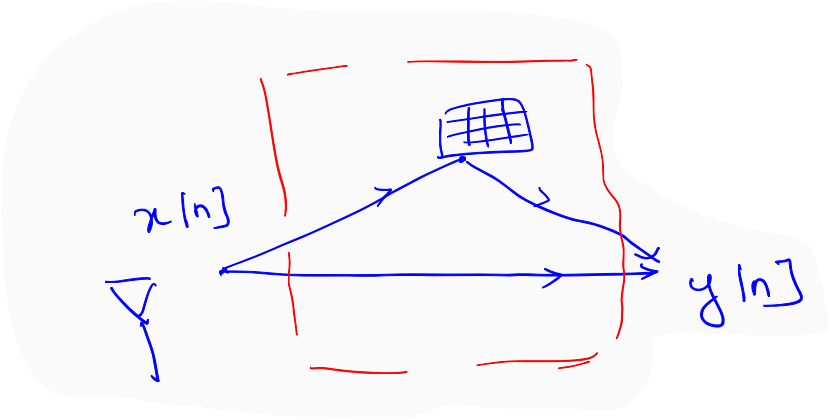

Suppose that the received sequence, $y[n]$ is 

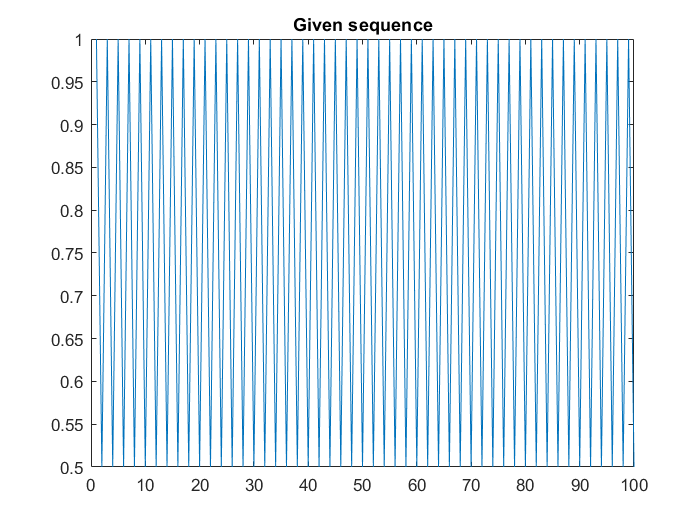

y = repmat([1.0 0.5],1, 50); 
plot(y)
title("Given sequence");

Now, recover $x[n]$ from this $y[n]$, i.e., get an estimate of $x[n], $ called as $\hat{x}[n]$, using a stable and causal filter. $x[n] $ and $\hat{x}[n]$must have the same amplitudes, but phases can be different.  

Hint: First do the minimum phase decomposition as follows: $H(z)  =  H_{\min}(z)H_{ap}(z)$ and pass $y[n]$ to the filter $1/H_{\min}(z)$ to get $\hat{x}[n]$. Refer to "Week-5 Video-3.mp4". See [https://spinlab.wpi.edu/courses/ece503_2014/7dot3.mp4](https://spinlab.wpi.edu/courses/ece503_2014/7dot3.mp4) for understanding why minimum phase systems are called as *minimum* phase systems. 

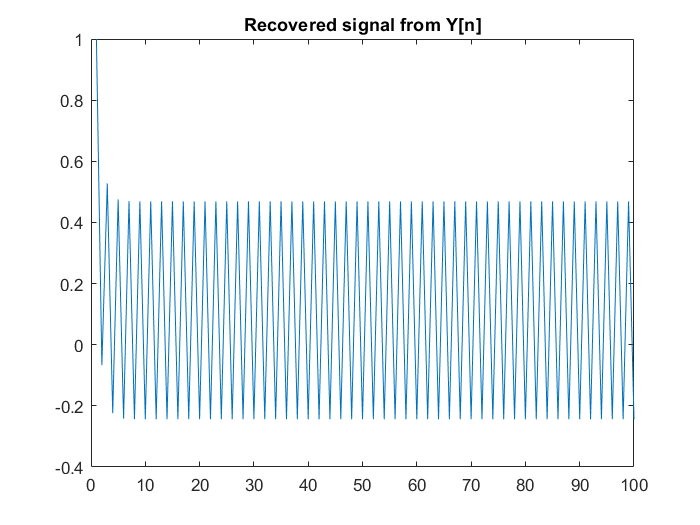

% WRITE YOUR CODE TO FIND AN ESTIMATE OF x[n], using minimum-phase -
% all-pass decomposition
b=[1 -1/3];   %The numerator of Hmin is 1-(1/3)z^-1
a=[1 -0.9];   %The denominator of Hmin is 1-0.9z^-1
%we use 1/Hmin for recovering
xhat=filter(a,b,y);
plot(xhat);
title("Recovered signal from Y[n]");

Hallpass=tf([-1/3 1],[1 -1/3],1,'Variable','z^-1') %Transfer function for Hall

Hallpass =
 
  -0.3333 + z^-1
  ---------------
  1 - 0.3333 z^-1
 
Sample time: 1 seconds
Discrete-time transfer function.



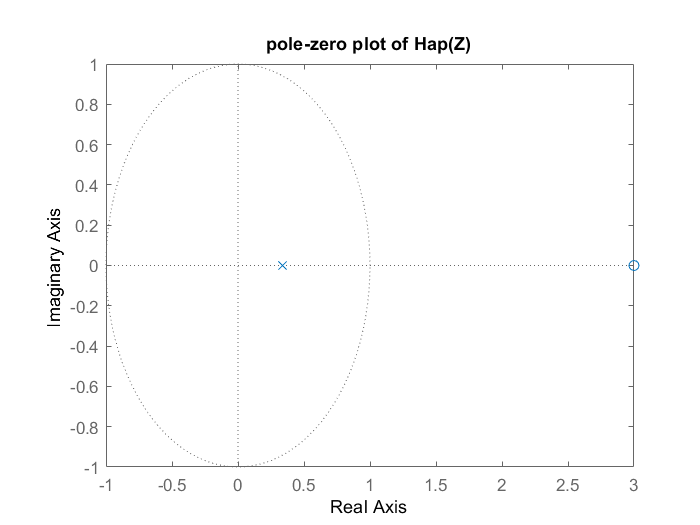

pzplot(Hallpass);
title("pole-zero plot of Hap(Z)");

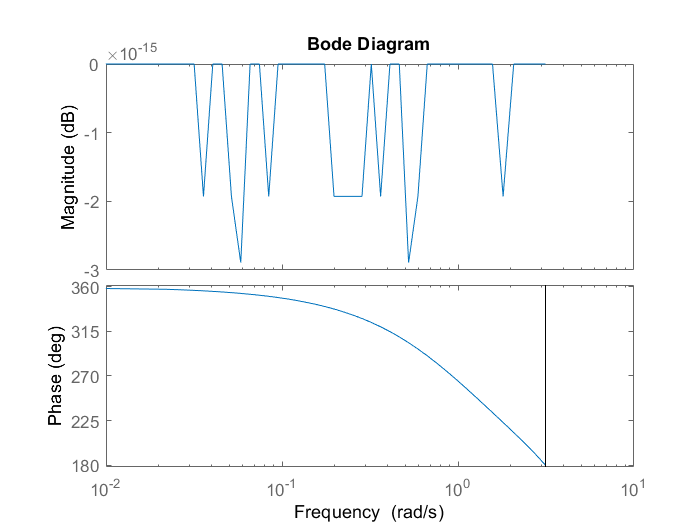

bode(Hallpass);

% w = linspace(-pi,pi,100);
% HH=freqz(Hallpass,w);
% mag=abs(HH);title('Magnitude response')
% figure
% phase=angle(HH);title('Phase response')
% plot(w,mag)
% plot(w,phase)
%xhat = []%

- Comment on the pole-zero locations of the all-pass filters. Where are the poles and zeros of the all-pass filter, in the minimum-phase - all pass decomposition of the above channel system function ($H(z)  =  H_{\min}(z)H_{ap}(z)$)? 

            *ANSWER  Zero is at 3(outside unit circle) and pole at 1/3 (In unit circle).*

- Plot the magnitude and phase responses  of the $H_{ap}(z)$ obtained above. Comment on their behaviour. 

            *ANSWER   *$H_{ap}(z)$=$\frac{z^{-1}-1/3}{1-1/3z^{-1}}$ .  

The magnitude keeps changing while phase goes on decreasing.

There are other filter design methods as well, as you might have noted in the Filter Designer tool. However, we are not interested in them in this course. You now have sufficient knowledge on filter design and analysis. Hence, if required, you should be able to pick them up easily when required. 

### Thank you!